# Primer  Examen Parcial de Robótica

## Introducción 

**1.1 Objetivo e hipótesis**

**Objetivo:** El presente reporte tiene como objetivo modelar y simular el modelo del comportamiento de un robot manipulador tipo SCARA con una configuración RRR, haciendo uso de las herramientas aprendidas en clase. Se desarrollarán las ecuaciones de la cinemática de su postura, de sus velocidades y de sus aceleraciones, directas e inversas, así como de su modelo dinámico directo e inverso; posteriormente, se hará uso de los modelos matemáticos para implementar el modelo en MATLAB y simularlo.

**Hipótesis:** Se plantea que los modelos cinemáticos y dinámicos desarrollados, fundamentados en la teoría de las transformaciones homogéneas, la cinemática clásica y las ecuaciones de Euler–Lagrange, serán suficientes para implementar una simulación del robot haciendo uso de MATLAB como herramienta principal, modelando de manera aproximada el comportamiento cinemático y dinámico del robot, asumiendo sus parámetros dísicos y geométricos.

**1.2 Justificación**

La metodología implementada en este reporte se fundamente en los contenidos revisados durante el curso de Robótico, entre los que destacan los conceptos:

- **Robot SCARA**

- Se trata de un tipo de robot utilizado en la industria, cuyo propósito común suele ser tareas de ensamblaje rápido. Es el acrónimo de *Selective Compliant Assembly Robot Arm *o *Selective Compliant Articulated Robot Arm*. Su movimiento se da enteramente sobre un plano horizontal, y planos paralelos al mismo, suelen ser más rápidos que robots cartesianos equivalentes.

- **Transformaciones homogéneas**

- Se trata de una representación de un movimiento rígido, que resulta de una combinación entre una rotación y una traslación principalmente. Se expresa mediante una matriz   que integra una matriz de rotación, un vector columna de traslación, un vector de perspectiva y un factor de escala. Para la mayoría de las aplicaciones en robótica, el vector de perspectiva es un vector de ceros y el factor de escala es igual a 1. Se usa principalmente para representar la pose de un cuerpo rígido en un sistema de referencia dado.

- 

- **Vector de Postura**

- Se trata de un vector que describe la posición y orientación del efector final conformado por un conjunto de variables dependientes de las variables de configuración del robot. 

- **Vector de Pose**

- Se trata de un vector que describe la posición y orientación del efector final utilizando sus coordenadas absolutas respecto a un sistema de referencia inercial.

- **Jacobiano**

- Es una matriz que relaciona las velocidades articulares con la velocidad lineal y angular del efector final del robot. Se describe por:

- 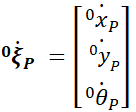es el vector de velocidades lineales y angulares del efector,

- 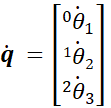es el vector de velocidades articulares,

-   es la matriz Jacobiana del sistema.

- El Jacobiano también se utiliza para calcular fuerzas y torques en las juntas, así como para analizar singularidades en la trayectoria del robot.

- **Formulación de Euler–Lagrange**

- Se trata de un método dinámico basado en la energía del sistema que se usa para obtener ecuaciones que describan el movimiento del sistema, así como para calcular las fuerzas y torques en las juntas del robot.

El procedimiento se basa en definir el **Lagrangiano**:

donde:

-   es la energía cinética total del sistema.

-   es la energía potencial total del sistema.

Las ecuaciones dinámicas resultan de aplicar, para cada coordenada generalizada  

Acorde con lo planteado en clase, este conjunto de conceptos debería ser suficiente para generar un modelo que describa el comportamiento aproximado del robot en su totalidad, cumpliendo con los atributos de egreso necesarios aportados al cursar la asignatura.

## Modelado del robot SCARA

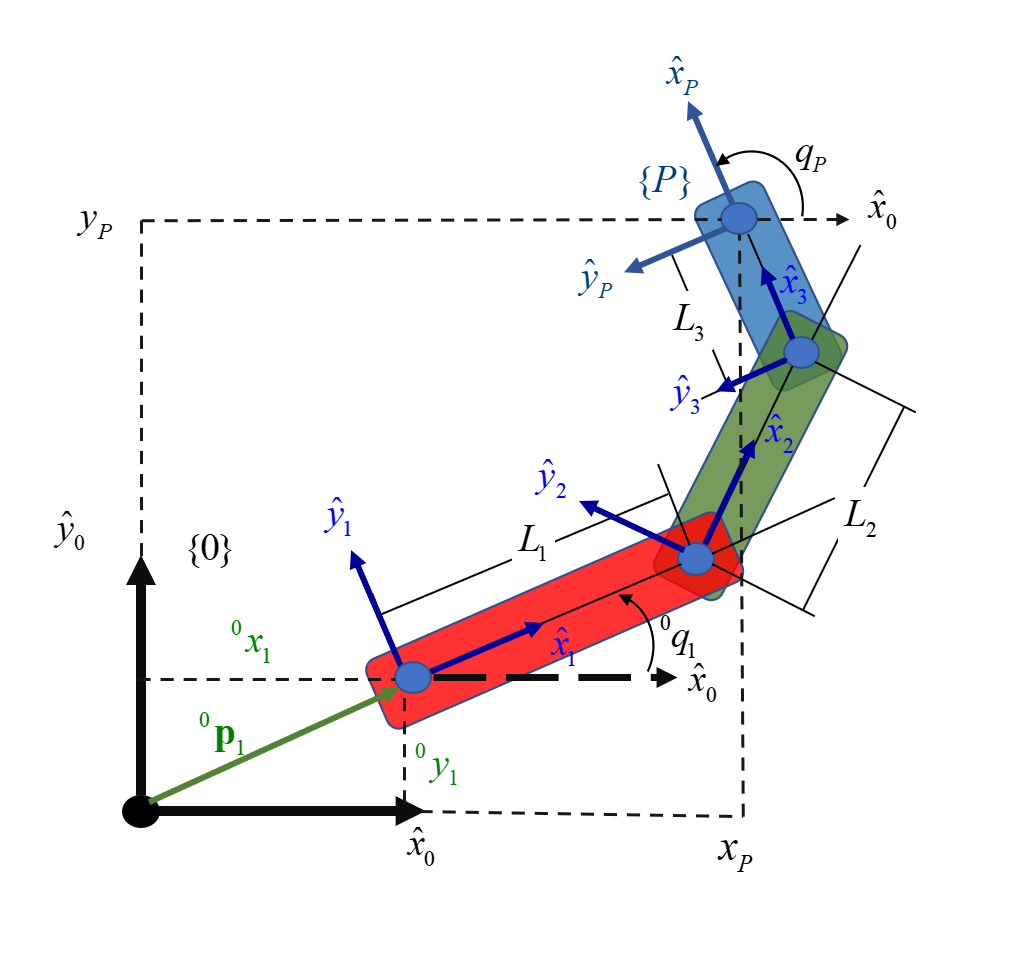

### Cinemática Directa de la Postura

#### Descripción del Modelo del Robot SCARA (RRR)

El robot SCARA planteado, cuenta con 3 juntas con un grado de libertad, que consiste en una rotación en el plano XY (RRR). La posición y orientación del efector final está determinada por las rotaciones de las 3 juntas.

#### Desarrollo de Transformaciones entre Sistemas de Referencia

**Transformación del sistema base al sistema del primer eslabón:**

Considerando un desplazamiento inicial   y una rotación alrededor del eje  :

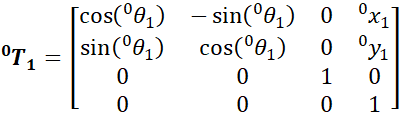

**Transformación del primer al segundo eslabón�:**

Esta transformación representa una rotación alrededor del eje   por el ángulo  � y una traslación en   igual a la longitud del primer eslabón  :

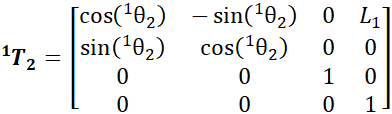

**Transformación del segundo al tercer eslabón:**

Similarmente, aquí ocurre una rotación por   y una traslación en   igual a  �:

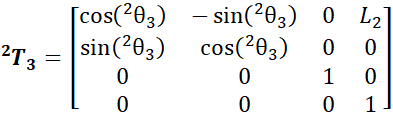

**Transformación del tercer eslabón al efector final:**

El último eslabón tiene únicamente una traslación en el eje   igual a  �, sin rotación adicional:

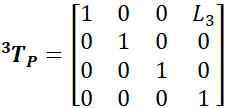

**Transformación total del sistema:**

La transformación total desde la base al efector se obtiene multiplicando todas las transformaciones intermedias:

**Vector de Postura**

El vector de postura del efector final respecto al sistema base se define como:

**Vector de Pose**

El vector de pose del efector final respecto al sistema base se define como:

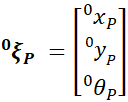

**Restricciones Cinemáticas de la Postura**

Las restricciones cinemáticas de la postura del sistema se definen como:

#### Implementación del Modelo

syms x_O_1 y_O_1 theta_O_1 L_2 theta_1_2 L_3 theta_2_3 L_1

%Deficición de la función de manera simbolica
syms Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j)

%Definición de la transformación homógenea general
Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j) = [cos(ai_j)*cos(bi_j) cos(ai_j)*sin(bi_j)*sin(gi_j)-sin(ai_j)*cos(gi_j) sin(ai_j)*sin(gi_j)+cos(ai_j)*sin(bi_j)*cos(gi_j) x_i_j; sin(ai_j)*cos(bi_j) cos(ai_j)*cos(gi_j)+sin(ai_j)*sin(bi_j)*sin(gi_j) sin(ai_j)*sin(bi_j)*cos(gi_j)-cos(ai_j)*sin(gi_j) y_i_j; -sin(bi_j) cos(bi_j)*sin(gi_j) cos(bi_j)*cos(gi_j) z_i_j; 0 0 0 1]

$$Tij(x\_i\_j, y\_i\_j, z\_i\_j, gi\_j, bi\_j, ai\_j) = \left(\begin{array}{cccc} \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)-\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)+\cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right) & x_{i,j}\\ \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)+\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)-\cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & y_{i,j}\\ -\sin\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right) & z_{i,j}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_O_1 = Tij(x_O_1,y_O_1,0,0,0,theta_O_1)

$$T\_O\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0 & x_{O,1}\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0 & y_{O,1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_1_2 = Tij(L_1,0,0,0,0,theta_1_2)

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{1,2}\right) & -\sin\left(\theta_{1,2}\right) & 0 & L_{1}\\ \sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_2_3 = Tij(L_2,0,0,0,0,theta_2_3)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{2,3}\right) & -\sin\left(\theta_{2,3}\right) & 0 & L_{2}\\ \sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_3_P = Tij(L_3,0,0,0,0,0)

$$T\_3\_P = \left(\begin{array}{cccc} 1 & 0 & 0 & L_{3}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_O_P = simplify(T_O_1*T_1_2*T_2_3*T_3_P)

$$T\_O\_P = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & x_{O,1}+L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+L_{3}\,\sigma_{2}\\ \sigma_{1} & \sigma_{2} & 0 & y_{O,1}+L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)+L_{3}\,\sigma_{1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

Vector de postura del robot

xi_O_P = [T_O_P(1,4);T_O_P(2,4);theta_O_1+theta_1_2+theta_2_3]

$$xi\_O\_P = \left(\begin{array}{c} x_{O,1}+L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ y_{O,1}+L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)+L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \theta_{1,2}+\theta_{2,3}+\theta_{O,1} \end{array}\right)$$

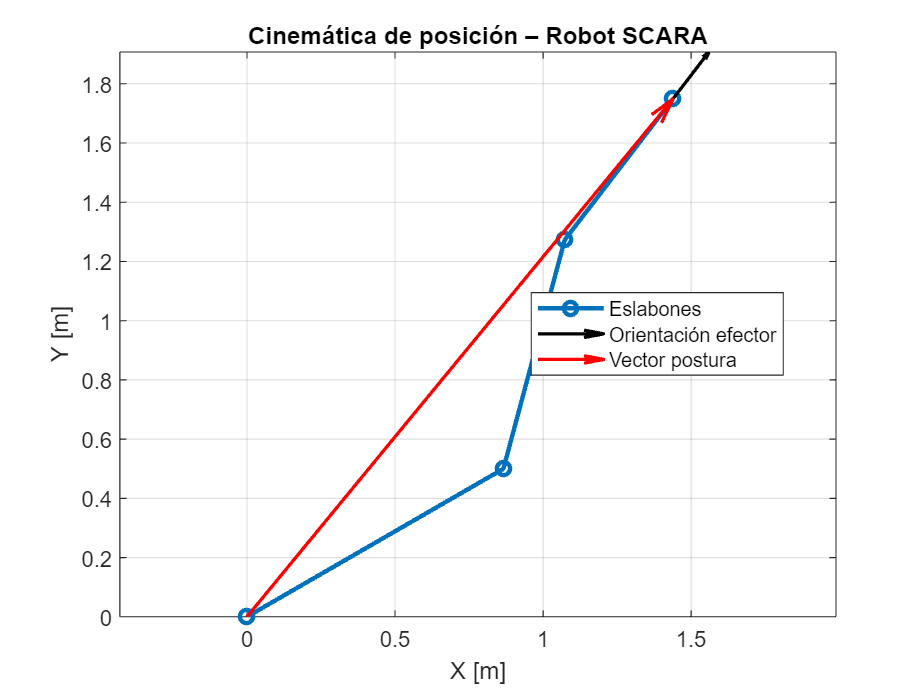

L1_s = 1.0; L2_s = 0.8; L3_s = 0.6;
x_O_1_s = 0; y_O_1_s = 0;
theta_O_1_s = pi/6; theta_1_2_s = pi/4; theta_2_3_s = -pi/8;

[P_s, xi_O_P_s] = direct_kin_scara(x_O_1_s, y_O_1_s, L1_s, L2_s, L3_s, ...
                                theta_O_1_s, theta_1_2_s, theta_2_3_s);
p0 = P_s(:,1); p1 = P_s(:,2); p2 = P_s(:,3); p3 = P_s(:,4);

figure
h_links = plot(P_s(1,:), P_s(2,:), '-o','LineWidth',2,'MarkerSize',6);
hold on
h_ori = quiver(p3(1), p3(2), 0.2*cos(xi_O_P_s(3)), 0.2*sin(xi_O_P_s(3)), ...
               0,'k','LineWidth',1.5,'MaxHeadSize',0.5);
h_post = quiver(p0(1), p0(2), xi_O_P_s(1)-p0(1), xi_O_P_s(2)-p0(2), ...
               0,'r','LineWidth',1.5,'MaxHeadSize',0.15);
hold off

axis equal, grid on
xlabel('X [m]'), ylabel('Y [m]')
title('Cinemática de posición – Robot SCARA')
legend([h_links,h_ori,h_post], ...
       'Eslabones','Orientación efector','Vector postura','Location','Best')


% Mostrar vector de postura
disp('Vector de postura [x; y; φ] =')

Vector de postura [x; y; φ] =


disp(xi_O_P)

$$\left(\begin{array}{c} x_{O,1}+L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ y_{O,1}+L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)+L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \theta_{1,2}+\theta_{2,3}+\theta_{O,1} \end{array}\right)$$

### Modelo cinemático inverso de la postura

La cinemática inversa permite determinar los valores de las variables articulares que debe adoptar el robot para alcanzar una posición y orientación deseadas del efector final. Este proceso es fundamental en tareas de planificación de trayectorias y control de movimientos.

Para el robot SCARA considerado, se conoce el **vector de postura deseado**:

y se desea obtener los ángulos articulares  ,   y   que permiten alcanzar esta configuración.

**Desarrollo del modelo cinemático inverso** 

- Primero, se corrige la posición deseada para considerar la última traslación L3L_3 del efector:

Estos representan las coordenadas corregidas hasta el extremo del tercer eslabón (antes del efector). 

- Posteriormente, se resuelve la geometría del plano para encontrar   usando el **Teorema del Coseno**:

Por lo tanto:

 

- Luego, se calcula   usando la relación:

Esta expresión surge al aplicar el método del ángulo intermedio en la geometría del robot.

- Finalmente, se determina   considerando que:

lo que asegura que la orientación del efector coincida con la orientación deseada.

#### Implementación del Modelo:

syms x_O_P y_O_P phi L_1 L_2 L_3 real

x_w = x_O_P - L_3*cos(phi);
y_w = y_O_P - L_3*sin(phi);

cos_q2 = ( x_w^2 + y_w^2 - L_1^2 - L_2^2 )/(2*L_1*L_2);
theta_1_2_inv = acos( cos_q2 );

theta_O_1_inv = atan2( y_w, x_w ) ...
              - atan2( L_2*sin(theta_1_2_inv), L_1 + L_2*cos(theta_1_2_inv) );

theta_2_3_inv = phi - theta_O_1_inv - theta_1_2_inv;

theta_inv = simplify([ theta_O_1_inv;
                       theta_1_2_inv;
                       theta_2_3_inv ]);

theta_inv

$$theta\_inv = \begin{array}{l} \left(\begin{array}{c} \text{atan2}\left(y_{O,P}-L_{3}\,\sin\left(\varphi \right),x_{O,P}-L_{3}\,\cos\left(\varphi \right)\right)-\sigma_{1}\\ \pi -\mathrm{acos}\left(\frac{\sigma_{2}}{2\,L_{1}\,L_{2}}\right)\\ \varphi -\pi +\mathrm{acos}\left(\frac{\sigma_{2}}{2\,L_{1}\,L_{2}}\right)-\text{atan2}\left(y_{O,P}-L_{3}\,\sin\left(\varphi \right),x_{O,P}-L_{3}\,\cos\left(\varphi \right)\right)+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\text{atan2}\left(L_{2}\,\sqrt{1-\frac{{\sigma_{2}}^{2}}{4\,{L_{1}}^{2}\,{L_{2}}^{2}}},L_{1}-\frac{\sigma_{2}}{2\,L_{1}}\right)\\ \sigma_{2}={L_{1}}^{2}+{L_{2}}^{2}-{\left(x_{O,P}-L_{3}\,\cos\left(\varphi \right)\right)}^{2}-{\left(y_{O,P}-L_{3}\,\sin\left(\varphi \right)\right)}^{2} \end{array}$$

L1_s = 1.0; L2_s = 0.8; L3_s = 0.6;
theta_O_1_s = pi/6; theta_1_2_s = pi/4; theta_2_3_s = -pi/8;

[~, xi_O_P_s] = direct_kin_scara(0, 0, L1_s, L2_s, L3_s, ...
                               theta_O_1_s, theta_1_2_s, theta_2_3_s);

theta_inv = inv_kin_scara(xi_O_P_s(1), xi_O_P_s(2), xi_O_P_s(3), ...
                          L1_s, L2_s, L3_s);

fprintf('Directos: θ₁=%.6f  θ₂=%.6f  θ₃=%.6f\n', ...
        theta_O_1_s, theta_1_2_s, theta_2_3_s);

Directos: θ₁=0.523599  θ₂=0.785398  θ₃=-0.392699


fprintf('Inversos: θ₁=%.6f  θ₂=%.6f  θ₃=%.6f\n', ...
        theta_inv(1), theta_inv(2), theta_inv(3));

Inversos: θ₁=0.523599  θ₂=0.785398  θ₃=-0.392699


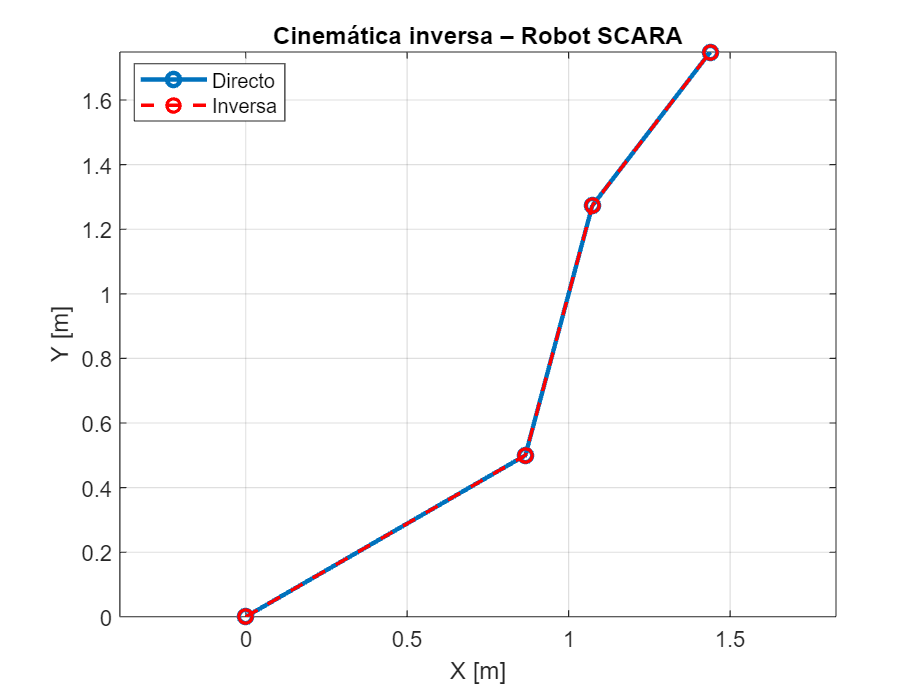


figure

[P, ~] = direct_kin_scara(0,0,L1_s,L2_s,L3_s,theta_O_1_s,theta_1_2_s,theta_2_3_s);
plot(P(1,:),P(2,:),'-o','LineWidth',2); hold on

p0 = P(:,1);
phi1_i = theta_inv(1);
p1_i   = p0 + L1_s*[cos(phi1_i); sin(phi1_i)];
phi2_i = phi1_i + theta_inv(2);
p2_i   = p1_i + L2_s*[cos(phi2_i); sin(phi2_i)];
phi3_i = phi2_i + theta_inv(3);
p3_i   = p2_i + L3_s*[cos(phi3_i); sin(phi3_i)];
plot([p0(1),p1_i(1),p2_i(1),p3_i(1)], ...
     [p0(2),p1_i(2),p2_i(2),p3_i(2)],'--or','LineWidth',1.5);

axis equal, grid on
xlabel('X [m]'), ylabel('Y [m]')
title('Cinemática inversa – Robot SCARA')
legend('Directo','Inversa','Location','Best')

### Modelo cinemático directo de las velocidades

**Planteamiento mediante el Jacobiano**

La velocidad del efector se expresa como función de las velocidades articulares a través de la matriz Jacobiana:

donde:

- es el vector de velocidades lineales y angulares del efector,

- es el vector de velocidades articulares,          

-   es la matriz Jacobiana del sistema.

La matriz Jacobiana se obtiene derivando el vector de postura   respecto a las variables articulares:

syms J_theta

J_theta 

$$J\_theta = J_{\theta }$$

J_theta = jacobian(xi_O_P,[theta_O_1, theta_1_2,theta_2_3])

$$J\_theta = \begin{array}{l} \left(\begin{array}{ccc} -L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{1}\,\sin\left(\theta_{O,1}\right)-\sigma_{1} & -L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-\sigma_{1} & -\sigma_{1}\\ L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{2} & L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+\sigma_{2} & \sigma_{2}\\ 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

syms theta_O_1 theta_1_2 theta_2_3 real
syms theta_dot_1 theta_dot_2 theta_dot_3 real      % d1 = \dot θ_{O,1}, d2 = \dot θ_{1,2}, d3 = \dot θ_{2,3}

q_dot = [theta_dot_1; theta_dot_2; theta_dot_3];

xidot = simplify( J_theta * q_dot );

xidot

$$xidot = \begin{array}{l} \left(\begin{array}{c} -{\dot{\theta }}_{1}\,\left(\sigma_{3}+L_{1}\,\sin\left(\theta_{O,1}\right)+\sigma_{1}\right)-{\dot{\theta }}_{2}\,\left(\sigma_{3}+\sigma_{1}\right)-L_{3}\,{\dot{\theta }}_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ {\dot{\theta }}_{2}\,\left(\sigma_{4}+\sigma_{2}\right)+{\dot{\theta }}_{1}\,\left(\sigma_{4}+L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{2}\right)+L_{3}\,{\dot{\theta }}_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ {\dot{\theta }}_{1}+{\dot{\theta }}_{2}+{\dot{\theta }}_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

L1_s = 1.0; L2_s = 0.8; L3_s = 0.6;
th1_s = pi/6; th2_s = pi/4; th3_s = -pi/8;
dth1_s = 0.2; dth2_s = 0.1; dth3_s = -0.05;

Jfunc = matlabFunction(J_theta, ...
    'Vars', {theta_O_1, theta_1_2, theta_2_3, L_1, L_2, L_3})

Jfunc = function_handle with value:
    @(theta_O_1,theta_1_2,theta_2_3,L_1,L_2,L_3)reshape([-L_2.*sin(theta_1_2+theta_O_1)-L_1.*sin(theta_O_1)-L_3.*sin(theta_1_2+theta_2_3+theta_O_1),L_2.*cos(theta_1_2+theta_O_1)+L_1.*cos(theta_O_1)+L_3.*cos(theta_1_2+theta_2_3+theta_O_1),1.0,-L_2.*sin(theta_1_2+theta_O_1)-L_3.*sin(theta_1_2+theta_2_3+theta_O_1),L_2.*cos(theta_1_2+theta_O_1)+L_3.*cos(theta_1_2+theta_2_3+theta_O_1),1.0,-L_3.*sin(theta_1_2+theta_2_3+theta_O_1),L_3.*cos(theta_1_2+theta_2_3+theta_O_1),1.0],[3,3])



xidot_s = direct_vel_scara(Jfunc, L1_s, L2_s, L3_s, ...
                           th1_s, th2_s, th3_s, ...
                           dth1_s, dth2_s, dth3_s);

fprintf('Velocidad efector (vx, vy, omega): [%.4f, %.4f, %.4f]', ...
        xidot_s(1), xidot_s(2), xidot_s(3));

Velocidad efector (vx, vy, omega): [-0.4508, 0.3266, 0.2500]

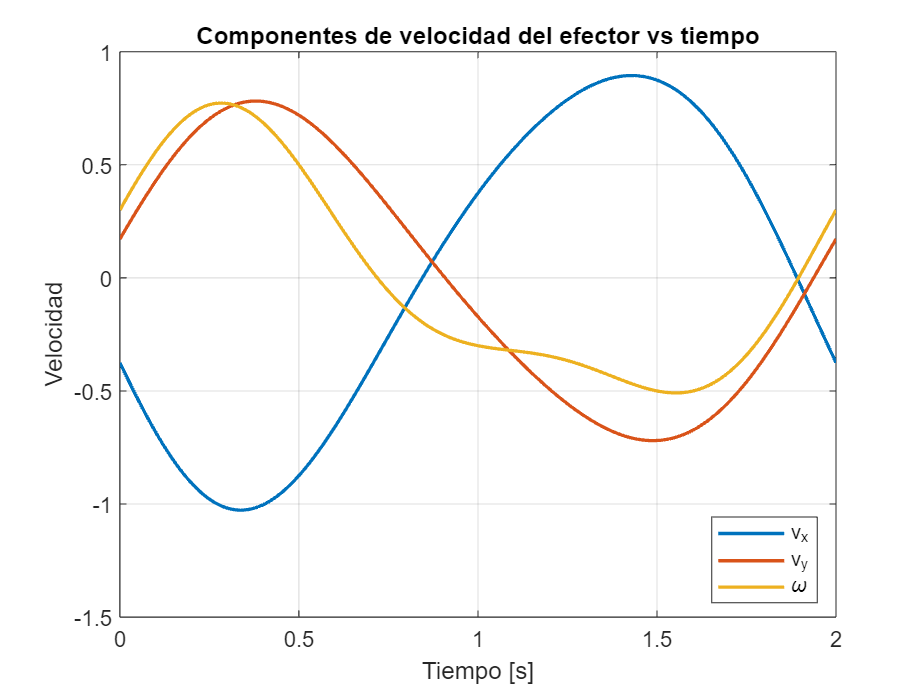

T = linspace(0,2,250);           % 0–2 s
dq1 = 0.5*sin(pi*T);             % [rad/s]
dq2 = 0.3*cos(pi*T);
dq3 = 0.2*sin(2*pi*T);

VEL = zeros(3,numel(T));

for k = 1:numel(T)
  VEL(:,k) = direct_vel_scara( Jfunc, ...
               L1_s, L2_s, L3_s, ...
               th1_s, th2_s, th3_s, ...
               dq1(k), dq2(k), dq3(k) );
end

figure
plot(T, VEL(1,:),'-', T, VEL(2,:),'-', T, VEL(3,:),'-','LineWidth',1.5);
legend('v_x','v_y','\omega','Location','Best')
xlabel('Tiempo [s]')
ylabel('Velocidad')
title('Componentes de velocidad del efector vs tiempo')
grid on

### Modelo cinemático inverso de las velocidades

**Deducción del modelo inverso usando el Jacobiano**

Cuando se conoce una velocidad deseada  del efector, las velocidades articulares necesarias para alcanzarla se obtienen mediante:

Donde:

-   es la matriz inversa del Jacobiano.

inv(J_theta)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}} & -\frac{\sin\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}} & \frac{L_{3}\,\sigma_{4}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{3}\,\sigma_{3}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}}\\ \frac{L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)}{\sigma_{1}} & \frac{L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)}{\sigma_{1}} & -\frac{L_{1}\,L_{3}\,\sigma_{4}\,\sin\left(\theta_{O,1}\right)-L_{1}\,L_{3}\,\sigma_{3}\,\cos\left(\theta_{O,1}\right)+L_{2}\,L_{3}\,\sigma_{4}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{2}\,L_{3}\,\sigma_{3}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{1}}\\ -\frac{\cos\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} & -\frac{\sin\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} & \frac{\sigma_{6}-\sigma_{5}+L_{3}\,\sigma_{4}\,\sin\left(\theta_{O,1}\right)-L_{3}\,\sigma_{3}\,\cos\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{1}\,L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right)-L_{1}\,L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{2}=L_{1}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right)-L_{1}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{3}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{5}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{6}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right) \end{array}$$

syms x_O_P y_O_P z_O_P real
syms x_dot_O_P y_dot_O_P theta_dot_O_P real      % x_dot = \dot x_{O,P}, y_dot = \dot y_{0,P}, z_dot = \dot z_{0,P}

xi_dot = [x_dot_O_P; y_dot_O_P; theta_dot_O_P];

q_dot = simplify( J_theta \ xi_dot );

q_dot

$$q\_dot = \left(\begin{array}{c} \frac{{\dot{x}}_{O,P}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+{\dot{y}}_{O,P}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{3}\,{\dot{\theta }}_{O,P}\,\sin\left(\theta_{2,3}\right)}{L_{1}\,\sin\left(\theta_{1,2}\right)}\\ -\frac{L_{1}\,{\dot{y}}_{O,P}\,\sin\left(\theta_{O,1}\right)+L_{2}\,{\dot{x}}_{O,P}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{2}\,{\dot{y}}_{O,P}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,{\dot{x}}_{O,P}\,\cos\left(\theta_{O,1}\right)+L_{1}\,L_{3}\,{\dot{\theta }}_{O,P}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+L_{2}\,L_{3}\,{\dot{\theta }}_{O,P}\,\sin\left(\theta_{2,3}\right)}{L_{1}\,L_{2}\,\sin\left(\theta_{1,2}\right)}\\ \frac{{\dot{x}}_{O,P}\,\cos\left(\theta_{O,1}\right)+{\dot{y}}_{O,P}\,\sin\left(\theta_{O,1}\right)+L_{2}\,{\dot{\theta }}_{O,P}\,\sin\left(\theta_{1,2}\right)+L_{3}\,{\dot{\theta }}_{O,P}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)}{L_{2}\,\sin\left(\theta_{1,2}\right)} \end{array}\right)$$


T = linspace(0,2,250);          % 0–2 seg
vx = 0.1*cos(pi*T);             % [m/s]
vy = 0.1*sin(pi*T);
omega = 0.2*cos(2*pi*T);        % [rad/s]

DQ_inv = zeros(3, numel(T));

for k = 1:numel(T)
    DQ_inv(:,k) = inv_vel_scara( ...
        Jfunc, L1_s, L2_s, L3_s, ...
        vx(k), vy(k), omega(k), ...
        th1_s, th2_s, th3_s );
end

disp(' k     dθ1      dθ2      dθ3');

 k     dθ1      dθ2      dθ3


for k = [1, round(numel(T)/2), numel(T)]
    fprintf('%3d %8.4f %8.4f %8.4f\n', ...
            k, DQ_inv(1,k), DQ_inv(2,k), DQ_inv(3,k));
end

  1  -0.0283  -0.2059   0.4343
125  -0.0998   0.1706   0.1291
250  -0.0283  -0.2059   0.4343


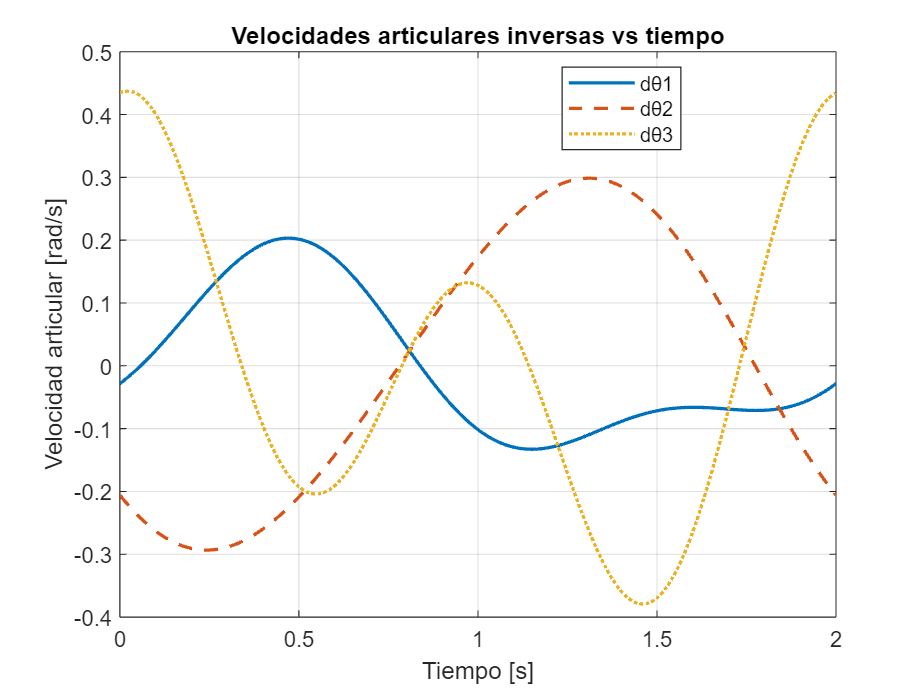


figure
plot(T, DQ_inv(1,:), '-', T, DQ_inv(2,:), '--', T, DQ_inv(3,:), ':', 'LineWidth', 1.5);
legend('dθ1','dθ2','dθ3','Location','Best');
xlabel('Tiempo [s]');
ylabel('Velocidad articular [rad/s]');
title('Velocidades articulares inversas vs tiempo');
grid on;

### Modelo cinemático directo de las aceleraciones

**Obtención de la derivada del Jacobiano**

La aceleración del efector  se expresa como:

donde:

- 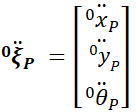es el vector de aceleraciones lineales y angulares del efector,

- 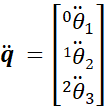es el vector de aceleraciones articulares,          

**Planteamiento de ecuaciones para el cálculo directo**

La derivada del Jacobiano se obtiene derivando cada elemento de J(θ)J(\theta) respecto a las variables articulares, y multiplicando por las velocidades articulares:

Así, el cálculo de la aceleración total del efector es la combinación de dos términos: 

- **Primer término:** efecto directo de las aceleraciones articulares a través del Jacobiano.

**Segundo término:** efecto indirecto de las velocidades articulares a través de la variación del Jacobiano.

syms theta_dot_O_1 theta_dot_1_2 theta_dot_2_3 real

q_dot = [theta_dot_O_1;
        theta_dot_1_2;
        theta_dot_2_3];

dJ_dq = jacobian( J_theta(:), ...
                  [theta_O_1, theta_1_2, theta_2_3] );   
J_theta_dot = reshape( dJ_dq * q_dot, size(J_theta) );

syms theta_ddot_O_1 theta_ddot_1_2 theta_ddot_2_3 real
q_ddot = [theta_ddot_O_1; theta_ddot_1_2; theta_ddot_2_3];

xi_ddot = simplify( J_theta*q_ddot + J_theta_dot*q_dot );

xi_ddot


L1_s   = 1.0; L2_s = 0.8; L3_s = 0.6;
th1_s  = pi/6; th2_s = pi/4; th3_s = -pi/8;
dth1_s = 0.2;  dth2_s = 0.1; dth3_s = -0.05;
ddth1_s = 0.5; ddth2_s = -0.3; ddth3_s = 0.1;

Jdotfunc = matlabFunction( J_theta_dot, ...
    'Vars', { theta_O_1,    theta_1_2,    theta_2_3, ...
              theta_dot_O_1,theta_dot_1_2,theta_dot_2_3, ...
              L_1,          L_2,          L_3 } );

xacc_s = direct_acc_scara(Jfunc, Jdotfunc, ...
                          L1_s, L2_s, L3_s, ...
                          th1_s, th2_s, th3_s, ...
                          dth1_s, dth2_s, dth3_s, ...
                          ddth1_s, ddth2_s, ddth3_s);

fprintf('Aceleraciones efector: ax=%.4f m/s^2, ay=%.4f m/s^2, alpha=%.4f rad/s^2\n', ...
        xacc_s(1), xacc_s(2), xacc_s(3));

Aceleraciones efector: ax=-0.6235 m/s^2, ay=0.4647 m/s^2, alpha=0.3000 rad/s^2


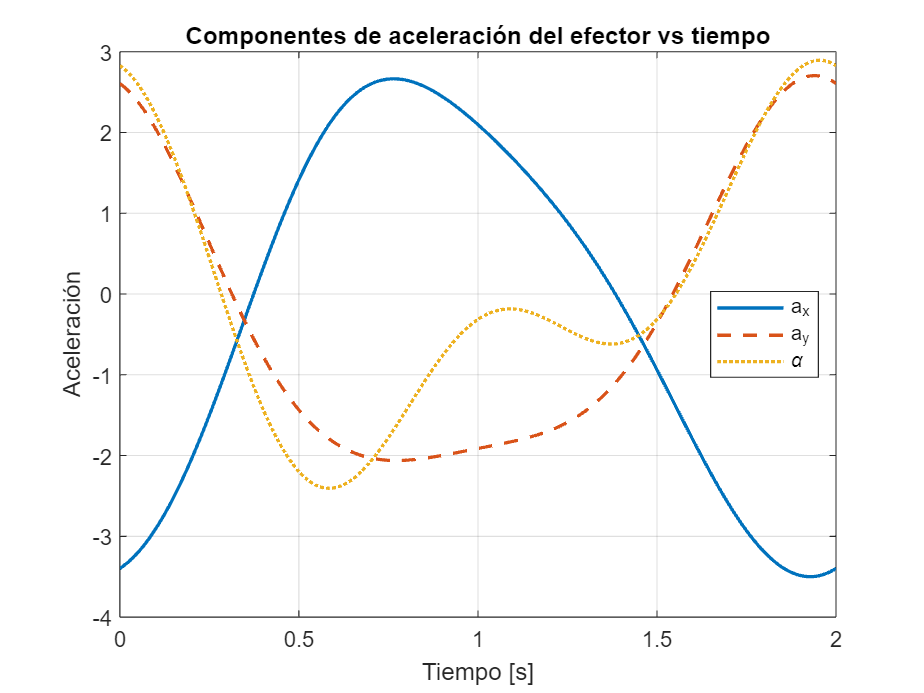


T = linspace(0,2,250);
dth1 = 0.5*sin(pi*T);      
dth2 = 0.3*cos(pi*T);
dth3 = 0.2*sin(2*pi*T);
ddth1 = 0.5*pi*cos(pi*T);  
ddth2 = -0.3*pi*sin(pi*T);
ddth3 = 0.4*pi*cos(2*pi*T);

ACC = zeros(3,length(T));
for k = 1:length(T)
  ACC(:,k) = direct_acc_scara(Jfunc, Jdotfunc, ...
                 L1_s, L2_s, L3_s, ...
                 th1_s, th2_s, th3_s, ...
                 dth1(k), dth2(k), dth3(k), ...
                 ddth1(k), ddth2(k), ddth3(k));
end

figure
plot(T, ACC(1,:),'-', T, ACC(2,:), '--', T, ACC(3,:), ':','LineWidth',1.5);
legend('a_x','a_y','\alpha','Location','Best');
xlabel('Tiempo [s]'); ylabel('Aceleración');
title('Componentes de aceleración del efector vs tiempo');
grid on;

### Modelo cinemático inverso de las aceleraciones

**Planteamiento y deducción del modelo inverso**

Cuando se tiene una aceleración deseada del efector , las aceleraciones articulares necesarias se obtienen resolviendo:

syms x_ddot_O_P y_ddot_O_P z_ddot_O_P real
xi_ddot = [x_ddot_O_P; y_ddot_O_P; z_ddot_O_P];

q_ddot_inv = simplify( J_theta \ ( xi_ddot - J_theta_dot*q_dot ) );
q_ddot_pinv = simplify( pinv(J_theta) * ( xi_ddot - J_theta_dot*q_dot ) );

q_ddot_inv

L1_s   = 1.0;  L2_s = 0.8;  L3_s = 0.6;
th1_s  = pi/6; th2_s = pi/4; th3_s = -pi/8;
dth1_s = 0.2;  dth2_s= 0.1; dth3_s = -0.05;
ddx_s  = 0.5;  ddy_s = -0.2; ddphi_s = 0.3;

ddth_s = inv_acc_scara(Jfunc, Jdotfunc, ...
                      L1_s, L2_s, L3_s, ...
                      th1_s, th2_s, th3_s, ...
                      dth1_s, dth2_s, dth3_s, ...
                      ddx_s, ddy_s, ddphi_s);

fprintf('Acel. articulares: [%.4f; %.4f; %.4f] rad/s^2\n', ddth_s);

Acel. articulares: [0.0032; -0.9356; 1.2324] rad/s^2


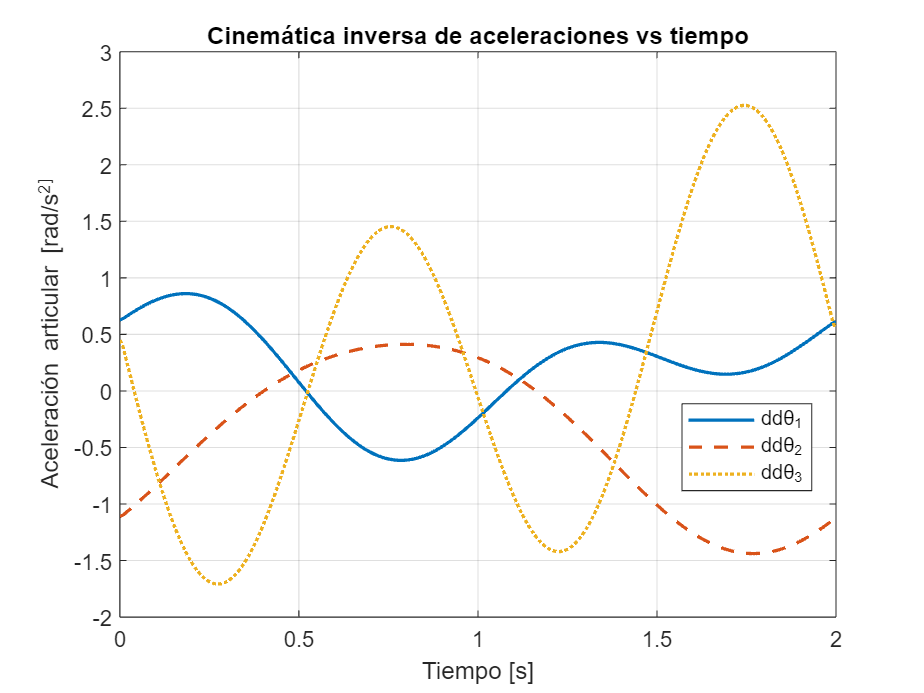


T = linspace(0,2,250);
vx = 0.1*cos(pi*T); vy = 0.1*sin(pi*T); omega = 0.2*cos(2*pi*T);
ddx = gradient(vx,T); ddy = gradient(vy,T); ddphi = gradient(omega,T);

DDTH = zeros(3,numel(T));
for k=1:numel(T)
  DDTH(:,k) = inv_acc_scara(Jfunc, Jdotfunc, ...
                L1_s,L2_s,L3_s, ...
                th1_s,th2_s,th3_s, ...
                dth1_s,dth2_s,dth3_s, ...
                ddx(k),ddy(k),ddphi(k));
end

figure
plot(T, DDTH(1,:),'-', T, DDTH(2,:), '--', T, DDTH(3,:), ':','LineWidth',1.5);
legend('ddθ_1','ddθ_2','ddθ_3','Location','Best');
xlabel('Tiempo [s]'); ylabel('Aceleración articular [rad/s^2]');
title('Cinemática inversa de aceleraciones vs tiempo');
grid on;

### Modelo dinámico por ecuaciones de Eüler-Lagrange

**Introducción al método de Euler-Lagrange**

El método de **Euler-Lagrange** permite obtener las ecuaciones dinámicas de un sistema mecánico a partir del balance entre su energía cinética y su energía potencial.

El procedimiento se basa en definir el **Lagrangiano**:

donde: 

-   es la energía cinética total del sistema.

-   es la energía potencial total del sistema.

Las ecuaciones dinámicas resultan de aplicar, para cada coordenada generalizada  

donde   es el torque aplicado en la articulación correspondiente.

Cada eslabón aporta: 

- **Energía cinética** (traslacional + rotacional):

- **Energía potencial** (por gravedad):

El **Lagrangiano total** del sistema es:

**Planteamiento de ecuaciones dinámicas inversas**

El **modelo dinámico inverso** tiene como objetivo calcular los **torques articulares**necesarios para generar un movimiento deseado, conocido el perfil de trayectoria  ,  , y  .

El modelo se basa directamente en la forma general obtenida mediante el método de Euler-Lagrange:

donde: 

-   es el vector de torques articulares,

-   es la matriz de inercia,

-   es el vector de fuerzas centrífugas y de Coriolis,

-   es el vector de fuerzas debidas a la gravedad.

Con esta formulación, para cualquier conjunto de  ,  , y  �, es posible calcular los torques requeridos para que el robot siga esa trayectoria.

**Simulación de los modelos dinámicos**

La simulación del modelo directo consistió en evaluar: 

- Trayectorias articulares definidas (senos y cosenos en el tiempo).

- Cálculo de torques   usando  ,   y  .

- Obtención de aceleraciones articulares  .

La simulación del modelo inverso consistió en evaluar: 

- Trayectorias articulares deseadas (senos y cosenos en el tiempo).

- Cálculo de torques   requeridos usando  ,   y  .

#### Implementación del Modelo

syms x_1_C1 theta_dot_O_1

v_C1_C1 = [0;x_1_C1*theta_dot_O_1;0]

$$v\_C1\_C1 = \left(\begin{array}{c} 0\\ {\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\\ 0 \end{array}\right)$$


v_O_C1 = [-x_1_C1*sin(theta_O_1)*theta_dot_O_1;x_1_C1*cos(theta_O_1)*theta_dot_O_1;0]

$$v\_O\_C1 = \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

transpose(v_C1_C1)*v_C1_C1

$$ans = {{\dot{\theta }}_{O,1}}^{2}\,{x_{1,\mathrm{C1}}}^{2}$$

simplify(transpose(v_O_C1)*v_O_C1)

$$ans = {{\dot{\theta }}_{O,1}}^{2}\,{x_{1,\mathrm{C1}}}^{2}$$

## Cálculo de la posición de los centros de masa

syms x_1_C1 x_2_C2 x_3_C3

T_1_C1 = Tij(x_1_C1,0,0,0,0,0)

$$T\_1\_C1 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{1,\mathrm{C1}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_O_C1 = T_O_1*T_1_C1

$$T\_O\_C1 = \left(\begin{array}{cccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0 & x_{O,1}+x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0 & y_{O,1}+x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_2_C2 = Tij(x_2_C2,0,0,0,0,0)

$$T\_2\_C2 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{2,\mathrm{C2}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_O_C2 = T_O_1*T_1_2*T_2_C2

$$T\_O\_C2 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)-\cos\left(\theta_{O,1}\right)\,\sin\left(\theta_{1,2}\right) & 0 & x_{O,1}+x_{2,\mathrm{C2}}\,\sigma_{1}+L_{1}\,\cos\left(\theta_{O,1}\right)\\ \sigma_{2} & \sigma_{1} & 0 & y_{O,1}+x_{2,\mathrm{C2}}\,\sigma_{2}+L_{1}\,\sin\left(\theta_{O,1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1,2}\right)\,\cos\left(\theta_{O,1}\right)-\sin\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)\\ \sigma_{2}=\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)+\cos\left(\theta_{O,1}\right)\,\sin\left(\theta_{1,2}\right) \end{array}$$


T_3_C3 = Tij(x_3_C3,0,0,0,0,0)

$$T\_3\_C3 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{3,\mathrm{C3}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_O_C3 = T_O_1*T_1_2*T_2_3*T_3_C3

$$T\_O\_C3 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\cos\left(\theta_{2,3}\right)\,\sigma_{4}-\sin\left(\theta_{2,3}\right)\,\sigma_{3} & 0 & x_{O,1}+L_{2}\,\sigma_{3}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{1}\\ \sigma_{2} & \sigma_{1} & 0 & y_{O,1}+L_{2}\,\sigma_{4}+L_{1}\,\sin\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{2,3}\right)\,\sigma_{3}-\sin\left(\theta_{2,3}\right)\,\sigma_{4}\\ \sigma_{2}=\cos\left(\theta_{2,3}\right)\,\sigma_{4}+\sin\left(\theta_{2,3}\right)\,\sigma_{3}\\ \sigma_{3}=\cos\left(\theta_{1,2}\right)\,\cos\left(\theta_{O,1}\right)-\sin\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)+\cos\left(\theta_{O,1}\right)\,\sin\left(\theta_{1,2}\right) \end{array}$$

%Vectores de posición
p_O_C1 = [T_O_C1(1,4);T_O_C1(2,4);T_O_C1(3,4)]

$$p\_O\_C1 = \left(\begin{array}{c} x_{O,1}+x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ y_{O,1}+x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

p_O_C2 = simplify([T_O_C2(1,4);T_O_C2(2,4);T_O_C2(3,4)])

$$p\_O\_C2 = \left(\begin{array}{c} x_{O,1}+x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)\\ y_{O,1}+x_{2,\mathrm{C2}}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$


p_O_C3 = simplify([T_O_C3(1,4);T_O_C3(2,4);T_O_C3(3,4)])

$$p\_O\_C3 = \left(\begin{array}{c} x_{O,1}+L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ y_{O,1}+x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)+L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

## Cálculo de las velocidades

syms theta_dot_O_1 theta_dot_1_2 theta_dot_2_3

v_O_C1 = diff(p_O_C1,theta_O_1)*theta_dot_O_1+diff(p_O_C1,theta_1_2)*theta_dot_1_2+diff(p_O_C1,theta_2_3)*theta_dot_2_3

$$v\_O\_C1 = \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

v_O_C2 = diff(p_O_C2,theta_O_1)*theta_dot_O_1+diff(p_O_C2,theta_1_2)*theta_dot_1_2+diff(p_O_C2,theta_2_3)*theta_dot_2_3

$$v\_O\_C2 = \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,\left(x_{2,\mathrm{C2}}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)\right)-{\dot{\theta }}_{1,2}\,x_{2,\mathrm{C2}}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,\left(x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)\right)+{\dot{\theta }}_{1,2}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ 0 \end{array}\right)$$

v_O_C3 = diff(p_O_C3,theta_O_1)*theta_dot_O_1+diff(p_O_C3,theta_1_2)*theta_dot_1_2+diff(p_O_C3,theta_2_3)*theta_dot_2_3

$$v\_O\_C3 = \begin{array}{l} \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,\left(\sigma_{1}+\sigma_{3}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)-{\dot{\theta }}_{1,2}\,\left(\sigma_{1}+\sigma_{3}\right)-{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,\left(\sigma_{4}+L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{2}\right)+{\dot{\theta }}_{1,2}\,\left(\sigma_{4}+\sigma_{2}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

### Cálculo de la velocidades angulares

syms omega_1_1 omega_2_2 omega_3_3
%Propagación para el primer cuerpo
omega_1_1

$$omega\_1\_1 = \omega_{1,1}$$

omega_O_O = [0;0;0]

omega_O_O =      0
     0
     0


n_1_1 = [0;0;1]

n_1_1 =      0
     0
     1


R_O_1 = [T_O_1(1,1),T_O_1(1,2),T_O_1(1,3);T_O_1(2,1),T_O_1(2,2),T_O_1(2,3);T_O_1(3,1),T_O_1(3,2),T_O_1(3,3)]

$$R\_O\_1 = \left(\begin{array}{ccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_1_O = transpose(R_O_1)

$$R\_1\_O = \left(\begin{array}{ccc} \cos\left(\theta_{O,1}\right) & \sin\left(\theta_{O,1}\right) & 0\\ -\sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


%Ecuación de propagación
omega_1_1 = R_1_O*omega_O_O+n_1_1*theta_dot_O_1

$$omega\_1\_1 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{O,1} \end{array}\right)$$


%Propagación para el segundo cuerpo
omega_2_2

$$omega\_2\_2 = \omega_{2,2}$$

n_2_2 = [0;0;1]

n_2_2 =      0
     0
     1


R_1_2 = [T_1_2(1,1),T_1_2(1,2),T_1_2(1,3);T_1_2(2,1),T_1_2(2,2),T_1_2(2,3);T_1_2(3,1),T_1_2(3,2),T_1_2(3,3)]

$$R\_1\_2 = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}\right) & -\sin\left(\theta_{1,2}\right) & 0\\ \sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_2_1 = transpose(R_1_2)

$$R\_2\_1 = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}\right) & \sin\left(\theta_{1,2}\right) & 0\\ -\sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


%Ecuación de propagación
omega_2_2 = R_2_1*omega_1_1+n_2_2*theta_dot_1_2

$$omega\_2\_2 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1} \end{array}\right)$$


%Propagación para el tercer cuerpo
omega_3_3

$$omega\_3\_3 = \omega_{3,3}$$

n_3_3 = [0;0;1]

n_3_3 =      0
     0
     1


R_2_3 = [T_2_3(1,1),T_2_3(1,2),T_2_3(1,3);T_2_3(2,1),T_2_3(2,2),T_2_3(2,3);T_2_3(3,1),T_2_3(3,2),T_2_3(3,3)]

$$R\_2\_3 = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & -\sin\left(\theta_{2,3}\right) & 0\\ \sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_3_2 = transpose(R_2_3)

$$R\_3\_2 = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & \sin\left(\theta_{2,3}\right) & 0\\ -\sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


%Ecuación de propagación
omega_3_3 = R_3_2*omega_2_2+n_3_3*theta_dot_2_3

$$omega\_3\_3 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1} \end{array}\right)$$

v_O_C3

$$v\_O\_C3 = \begin{array}{l} \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,\left(\sigma_{1}+\sigma_{3}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)-{\dot{\theta }}_{1,2}\,\left(\sigma_{1}+\sigma_{3}\right)-{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,\left(\sigma_{4}+L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{2}\right)+{\dot{\theta }}_{1,2}\,\left(\sigma_{4}+\sigma_{2}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

## Defición de los elementos de inercia 

syms g I_xx1 I_yy1 I_zz1 I_xx2 I_yy2 I_zz2 I_xx3 I_yy3 I_zz3
%vector de gravedad

g_v = [0;-g;0]

$$g\_v = \left(\begin{array}{c} 0\\ -g\\ 0 \end{array}\right)$$


I_C1 = [I_xx1,0,0;0,I_yy1,0;0,0,I_zz1]

$$I\_C1 = \left(\begin{array}{ccc} I_{\mathrm{xx1}} & 0 & 0\\ 0 & I_{\mathrm{yy1}} & 0\\ 0 & 0 & I_{\mathrm{zz1}} \end{array}\right)$$

I_C2 = [I_xx2,0,0;0,I_yy2,0;0,0,I_zz2]

$$I\_C2 = \left(\begin{array}{ccc} I_{\mathrm{xx2}} & 0 & 0\\ 0 & I_{\mathrm{yy2}} & 0\\ 0 & 0 & I_{\mathrm{zz2}} \end{array}\right)$$

I_C3 = [I_xx3,0,0;0,I_yy3,0;0,0,I_zz3]

$$I\_C3 = \left(\begin{array}{ccc} I_{\mathrm{xx3}} & 0 & 0\\ 0 & I_{\mathrm{yy3}} & 0\\ 0 & 0 & I_{\mathrm{zz3}} \end{array}\right)$$

Cáculo del Lagrangeano

syms m_1 m_2 m_3
%energía cinética de cada uno de los cuerpos

k_1 = simplify((m_1/2)*transpose(v_O_C1)*v_O_C1+(1/2)*transpose(omega_1_1)*I_C1*omega_1_1)

$$k\_1 = \frac{{{\dot{\theta }}_{O,1}}^{2}\,\left(m_{1}\,{x_{1,\mathrm{C1}}}^{2}+I_{\mathrm{zz1}}\right)}{2}$$


k_2 = simplify((m_2/2)*transpose(v_O_C2)*v_O_C2+(1/2)*transpose(omega_2_2)*I_C2*omega_2_2)

$$k\_2 = \frac{m_{2}\,{L_{1}}^{2}\,{{\dot{\theta }}_{O,1}}^{2}}{2}+m_{2}\,\cos\left(\theta_{1,2}\right)\,L_{1}\,{\dot{\theta }}_{1,2}\,{\dot{\theta }}_{O,1}\,x_{2,\mathrm{C2}}+m_{2}\,\cos\left(\theta_{1,2}\right)\,L_{1}\,{{\dot{\theta }}_{O,1}}^{2}\,x_{2,\mathrm{C2}}+\frac{m_{2}\,{{\dot{\theta }}_{1,2}}^{2}\,{x_{2,\mathrm{C2}}}^{2}}{2}+\frac{I_{\mathrm{zz2}}\,{{\dot{\theta }}_{1,2}}^{2}}{2}+m_{2}\,{\dot{\theta }}_{1,2}\,{\dot{\theta }}_{O,1}\,{x_{2,\mathrm{C2}}}^{2}+I_{\mathrm{zz2}}\,{\dot{\theta }}_{1,2}\,{\dot{\theta }}_{O,1}+\frac{m_{2}\,{{\dot{\theta }}_{O,1}}^{2}\,{x_{2,\mathrm{C2}}}^{2}}{2}+\frac{I_{\mathrm{zz2}}\,{{\dot{\theta }}_{O,1}}^{2}}{2}$$


k_3 = simplify((m_3/2)*transpose(v_O_C3)*v_O_C3+(1/2)*transpose(omega_3_3)*I_C3*omega_3_3)

$$k\_3 = \begin{array}{l} \frac{m_{3}\,{\left({\dot{\theta }}_{O,1}\,\left(\sigma_{2}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+{\dot{\theta }}_{1,2}\,\left(\sigma_{2}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{4}\right)}^{2}}{2}+\frac{m_{3}\,{\left({\dot{\theta }}_{O,1}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)+{\dot{\theta }}_{1,2}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{3}\right)}^{2}}{2}+I_{\mathrm{zz3}}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{2,3}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{2}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{3}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

% Cáclulo de la energía potencial de cada cuerpo

u_1 = -m_1*transpose(p_O_C1)*g_v

$$u\_1 = g\,m_{1}\,\left(y_{O,1}+x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\right)$$

u_2 = -m_2*transpose(p_O_C2)*g_v

$$u\_2 = g\,m_{2}\,\left(y_{O,1}+x_{2,\mathrm{C2}}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)\right)$$

u_3 = -m_3*transpose(p_O_C3)*g_v

$$u\_3 = g\,m_{3}\,\left(y_{O,1}+x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)+L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)\right)$$

### Cálculo del Lagrangeano


La = (k_1+k_2+k_3)-(u_1+u_2+u_3)

## Cálculo de los pares

syms theta_ddot_O_1 theta_ddot_1_2 theta_ddot_2_3

D_theta1 = diff(La,theta_dot_O_1)

$$D\_theta1 = \begin{array}{l} I_{\mathrm{zz2}}\,{\dot{\theta }}_{1,2}+I_{\mathrm{zz2}}\,{\dot{\theta }}_{O,1}+{\dot{\theta }}_{O,1}\,\left(m_{1}\,{x_{1,\mathrm{C1}}}^{2}+I_{\mathrm{zz1}}\right)+\frac{I_{\mathrm{zz3}}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)}{2}+I_{\mathrm{zz3}}\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{2,3}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)+m_{2}\,{\dot{\theta }}_{1,2}\,{x_{2,\mathrm{C2}}}^{2}+m_{2}\,{\dot{\theta }}_{O,1}\,{x_{2,\mathrm{C2}}}^{2}+m_{3}\,\sigma_{1}\,\left({\dot{\theta }}_{O,1}\,\sigma_{1}+{\dot{\theta }}_{1,2}\,\left(\sigma_{3}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{4}\right)+m_{3}\,\sigma_{2}\,\left({\dot{\theta }}_{O,1}\,\sigma_{2}+{\dot{\theta }}_{1,2}\,\left(x_{3,\mathrm{C3}}\,\sigma_{6}+\sigma_{5}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{6}\right)+{L_{1}}^{2}\,m_{2}\,{\dot{\theta }}_{O,1}+L_{1}\,m_{2}\,{\dot{\theta }}_{1,2}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)+2\,L_{1}\,m_{2}\,{\dot{\theta }}_{O,1}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{3}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{4}\\ \sigma_{2}=x_{3,\mathrm{C3}}\,\sigma_{6}+\sigma_{5}+L_{1}\,\sin\left(\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{5}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{6}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

tao_1 = diff(D_theta1,theta_O_1)*theta_dot_O_1 + diff(D_theta1,theta_1_2)*theta_dot_1_2 + diff(D_theta1,theta_2_3)*theta_dot_2_3 + diff(D_theta1,theta_dot_O_1)*theta_ddot_O_1+ diff(D_theta1,theta_dot_1_2)*theta_ddot_1_2+ diff(D_theta1,theta_dot_2_3)*theta_ddot_2_3-diff(La,theta_O_1)

D_theta2 = diff(La,theta_dot_1_2)

$$D\_theta2 = \begin{array}{l} I_{\mathrm{zz2}}\,{\dot{\theta }}_{1,2}+I_{\mathrm{zz2}}\,{\dot{\theta }}_{O,1}+\frac{I_{\mathrm{zz3}}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)}{2}+I_{\mathrm{zz3}}\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{2,3}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)+m_{2}\,{\dot{\theta }}_{1,2}\,{x_{2,\mathrm{C2}}}^{2}+m_{2}\,{\dot{\theta }}_{O,1}\,{x_{2,\mathrm{C2}}}^{2}+m_{3}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}\right)\,\left({\dot{\theta }}_{O,1}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)+{\dot{\theta }}_{1,2}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{3}\right)+m_{3}\,\left(\sigma_{2}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)\,\left({\dot{\theta }}_{O,1}\,\left(\sigma_{2}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+{\dot{\theta }}_{1,2}\,\left(\sigma_{2}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{4}\right)+L_{1}\,m_{2}\,{\dot{\theta }}_{O,1}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{2}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{3}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

tao_2 = diff(D_theta2,theta_O_1)*theta_dot_O_1 + diff(D_theta2,theta_1_2)*theta_dot_1_2 + diff(D_theta2,theta_2_3)*theta_dot_2_3 + diff(D_theta2,theta_dot_O_1)*theta_ddot_O_1+ diff(D_theta2,theta_dot_1_2)*theta_ddot_1_2+ diff(D_theta2,theta_dot_2_3)*theta_ddot_2_3-diff(La,theta_1_2)

D_theta3 = diff(La,theta_dot_2_3)

$$D\_theta3 = \begin{array}{l} \frac{I_{\mathrm{zz3}}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)}{2}+I_{\mathrm{zz3}}\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{2,3}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{1}\,\left({\dot{\theta }}_{O,1}\,\left(x_{3,\mathrm{C3}}\,\sigma_{1}+\sigma_{3}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)+{\dot{\theta }}_{1,2}\,\left(x_{3,\mathrm{C3}}\,\sigma_{1}+\sigma_{3}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{1}\right)+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{2}\,\left({\dot{\theta }}_{O,1}\,\left(\sigma_{4}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{2}\right)+{\dot{\theta }}_{1,2}\,\left(\sigma_{4}+x_{3,\mathrm{C3}}\,\sigma_{2}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{2}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

tao_3 = diff(D_theta3,theta_O_1)*theta_dot_O_1 + diff(D_theta3,theta_1_2)*theta_dot_1_2 + diff(D_theta3,theta_2_3)*theta_dot_2_3 + diff(D_theta3,theta_dot_O_1)*theta_ddot_O_1+ diff(D_theta3,theta_dot_1_2)*theta_ddot_1_2+ diff(D_theta3,theta_dot_2_3)*theta_ddot_2_3-diff(La,theta_2_3)

tao = [tao_1;tao_2;tao_3]

% Cálculo de la matriz de inercia

M1 = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[1,0,0,0,0,0,0])

$$M1 = \begin{array}{l} \left(\begin{array}{c} I_{\mathrm{zz1}}+I_{\mathrm{zz2}}+I_{\mathrm{zz3}}+m_{3}\,{\sigma_{1}}^{2}+{L_{1}}^{2}\,m_{2}+m_{3}\,{\sigma_{2}}^{2}+m_{1}\,{x_{1,\mathrm{C1}}}^{2}+m_{2}\,{x_{2,\mathrm{C2}}}^{2}+2\,L_{1}\,m_{2}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)\\ m_{2}\,{x_{2,\mathrm{C2}}}^{2}+L_{1}\,m_{2}\,\cos\left(\theta_{1,2}\right)\,x_{2,\mathrm{C2}}+I_{\mathrm{zz2}}+I_{\mathrm{zz3}}+m_{3}\,\left(\sigma_{3}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)\,\sigma_{1}+m_{3}\,\left(x_{3,\mathrm{C3}}\,\sigma_{6}+\sigma_{5}\right)\,\sigma_{2}\\ I_{\mathrm{zz3}}+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{4}\,\sigma_{1}+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{6}\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{3}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{4}\\ \sigma_{2}=x_{3,\mathrm{C3}}\,\sigma_{6}+\sigma_{5}+L_{1}\,\sin\left(\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{5}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{6}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

M2 = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,1,0,0,0,0,0])

$$M2 = \begin{array}{l} \left(\begin{array}{c} m_{2}\,{x_{2,\mathrm{C2}}}^{2}+L_{1}\,m_{2}\,\cos\left(\theta_{1,2}\right)\,x_{2,\mathrm{C2}}+I_{\mathrm{zz2}}+I_{\mathrm{zz3}}+m_{3}\,\left(\sigma_{2}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)\,\left(\sigma_{2}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+m_{3}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}\right)\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)\\ I_{\mathrm{zz2}}+I_{\mathrm{zz3}}+m_{2}\,{x_{2,\mathrm{C2}}}^{2}+m_{3}\,{\left(\sigma_{2}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)}^{2}+m_{3}\,{\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}\right)}^{2}\\ I_{\mathrm{zz3}}+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{4}\,\left(\sigma_{2}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{3}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{2}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{3}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

M3 = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,0,1,0,0,0,0])

$$M3 = \begin{array}{l} \left(\begin{array}{c} I_{\mathrm{zz3}}+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{2}\,\left(\sigma_{4}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{2}\right)+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{1}\,\left(x_{3,\mathrm{C3}}\,\sigma_{1}+\sigma_{3}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)\\ I_{\mathrm{zz3}}+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{2}\,\left(\sigma_{4}+x_{3,\mathrm{C3}}\,\sigma_{2}\right)+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{1}\,\left(x_{3,\mathrm{C3}}\,\sigma_{1}+\sigma_{3}\right)\\ m_{3}\,{x_{3,\mathrm{C3}}}^{2}\,{\sigma_{2}}^{2}+m_{3}\,{x_{3,\mathrm{C3}}}^{2}\,{\sigma_{1}}^{2}+I_{\mathrm{zz3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

M_theta = collect([M1 M2 M3],[m_1,m_2,m_3])

$$M\_theta = \begin{array}{l} \left(\begin{array}{ccc} {x_{1,\mathrm{C1}}}^{2}\,m_{1}+\left({L_{1}}^{2}+2\,\cos\left(\theta_{1,2}\right)\,L_{1}\,x_{2,\mathrm{C2}}+{x_{2,\mathrm{C2}}}^{2}\right)\,m_{2}+\left({\sigma_{4}}^{2}+{\sigma_{5}}^{2}\right)\,m_{3}+I_{\mathrm{zz1}}+I_{\mathrm{zz2}}+I_{\mathrm{zz3}} & \sigma_{1} & \sigma_{2}\\ \sigma_{1} & {x_{2,\mathrm{C2}}}^{2}\,m_{2}+\left({\left(\sigma_{7}+x_{3,\mathrm{C3}}\,\sigma_{6}\right)}^{2}+{\left(x_{3,\mathrm{C3}}\,\sigma_{8}+\sigma_{9}\right)}^{2}\right)\,m_{3}+I_{\mathrm{zz2}}+I_{\mathrm{zz3}} & \sigma_{3}\\ \sigma_{2} & \sigma_{3} & \left({x_{3,\mathrm{C3}}}^{2}\,{\sigma_{6}}^{2}+{x_{3,\mathrm{C3}}}^{2}\,{\sigma_{8}}^{2}\right)\,m_{3}+I_{\mathrm{zz3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left({x_{2,\mathrm{C2}}}^{2}+L_{1}\,\cos\left(\theta_{1,2}\right)\,x_{2,\mathrm{C2}}\right)\,m_{2}+\left(\left(\sigma_{7}+x_{3,\mathrm{C3}}\,\sigma_{6}\right)\,\sigma_{4}+\left(x_{3,\mathrm{C3}}\,\sigma_{8}+\sigma_{9}\right)\,\sigma_{5}\right)\,m_{3}+I_{\mathrm{zz2}}+I_{\mathrm{zz3}}\\ \sigma_{2}=\left(x_{3,\mathrm{C3}}\,\sigma_{6}\,\sigma_{4}+x_{3,\mathrm{C3}}\,\sigma_{8}\,\sigma_{5}\right)\,m_{3}+I_{\mathrm{zz3}}\\ \sigma_{3}=\left(x_{3,\mathrm{C3}}\,\sigma_{6}\,\left(\sigma_{7}+x_{3,\mathrm{C3}}\,\sigma_{6}\right)+x_{3,\mathrm{C3}}\,\sigma_{8}\,\left(x_{3,\mathrm{C3}}\,\sigma_{8}+\sigma_{9}\right)\right)\,m_{3}+I_{\mathrm{zz3}}\\ \sigma_{4}=\sigma_{7}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{6}\\ \sigma_{5}=x_{3,\mathrm{C3}}\,\sigma_{8}+\sigma_{9}+L_{1}\,\sin\left(\theta_{O,1}\right)\\ \sigma_{6}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{7}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{8}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{9}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

### Cálculo del vector de pares por efecto de Coriolis

V_theta = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,0,0,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,0])

G_theta = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,0,0,0,0,0,g])

$$G\_theta = \begin{array}{l} \left(\begin{array}{c} g\,m_{3}\,\left(\sigma_{2}+L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{1}\right)+g\,m_{2}\,\left(x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)\right)+g\,m_{1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ g\,m_{3}\,\left(\sigma_{2}+\sigma_{1}\right)+g\,m_{2}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ g\,m_{3}\,x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

### Cálculo del modelo  Dinámico inverso

syms theta_ddot_O_1 theta_ddot_1_2 theta_ddot_2_3 real
q_ddot = [theta_ddot_O_1;
          theta_ddot_1_2;
          theta_ddot_2_3];

tau_inv = simplify( M_theta*q_ddot + V_theta + G_theta );

tau_inv1 = tau_inv(1)

tau_inv2 = tau_inv(2)

$$tau\_inv2 = I_{\mathrm{zz2}}\,{\ddot{\theta }}_{1,2}+I_{\mathrm{zz3}}\,{\ddot{\theta }}_{1,2}+I_{\mathrm{zz3}}\,{\ddot{\theta }}_{2,3}+I_{\mathrm{zz2}}\,{\ddot{\theta }}_{O,1}+I_{\mathrm{zz3}}\,{\ddot{\theta }}_{O,1}+m_{2}\,{\ddot{\theta }}_{1,2}\,{x_{2,\mathrm{C2}}}^{2}+m_{3}\,{\ddot{\theta }}_{1,2}\,{x_{3,\mathrm{C3}}}^{2}+m_{3}\,{\ddot{\theta }}_{2,3}\,{x_{3,\mathrm{C3}}}^{2}+m_{2}\,{\ddot{\theta }}_{O,1}\,{x_{2,\mathrm{C2}}}^{2}+m_{3}\,{\ddot{\theta }}_{O,1}\,{x_{3,\mathrm{C3}}}^{2}+{L_{2}}^{2}\,m_{3}\,{\ddot{\theta }}_{1,2}+{L_{2}}^{2}\,m_{3}\,{\ddot{\theta }}_{O,1}+L_{2}\,g\,m_{3}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+g\,m_{2}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+g\,m_{3}\,x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)+L_{1}\,m_{3}\,{{\dot{\theta }}_{O,1}}^{2}\,x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+L_{1}\,L_{2}\,m_{3}\,{{\dot{\theta }}_{O,1}}^{2}\,\sin\left(\theta_{1,2}\right)-L_{2}\,m_{3}\,{{\dot{\theta }}_{2,3}}^{2}\,x_{3,\mathrm{C3}}\,\sin\left(\theta_{2,3}\right)+L_{1}\,m_{2}\,{{\dot{\theta }}_{O,1}}^{2}\,x_{2,\mathrm{C2}}\,\sin\left(\theta_{1,2}\right)+L_{1}\,m_{3}\,{\ddot{\theta }}_{O,1}\,x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+L_{1}\,L_{2}\,m_{3}\,{\ddot{\theta }}_{O,1}\,\cos\left(\theta_{1,2}\right)+2\,L_{2}\,m_{3}\,{\ddot{\theta }}_{1,2}\,x_{3,\mathrm{C3}}\,\cos\left(\theta_{2,3}\right)+L_{2}\,m_{3}\,{\ddot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\cos\left(\theta_{2,3}\right)+L_{1}\,m_{2}\,{\ddot{\theta }}_{O,1}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)+2\,L_{2}\,m_{3}\,{\ddot{\theta }}_{O,1}\,x_{3,\mathrm{C3}}\,\cos\left(\theta_{2,3}\right)-2\,L_{2}\,m_{3}\,{\dot{\theta }}_{1,2}\,{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sin\left(\theta_{2,3}\right)-2\,L_{2}\,m_{3}\,{\dot{\theta }}_{2,3}\,{\dot{\theta }}_{O,1}\,x_{3,\mathrm{C3}}\,\sin\left(\theta_{2,3}\right)$$

tau_inv3 = tau_inv(3)

$$tau\_inv3 = I_{\mathrm{zz3}}\,{\ddot{\theta }}_{1,2}+I_{\mathrm{zz3}}\,{\ddot{\theta }}_{2,3}+I_{\mathrm{zz3}}\,{\ddot{\theta }}_{O,1}+m_{3}\,{\ddot{\theta }}_{1,2}\,{x_{3,\mathrm{C3}}}^{2}+m_{3}\,{\ddot{\theta }}_{2,3}\,{x_{3,\mathrm{C3}}}^{2}+m_{3}\,{\ddot{\theta }}_{O,1}\,{x_{3,\mathrm{C3}}}^{2}+g\,m_{3}\,x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)+L_{1}\,m_{3}\,{{\dot{\theta }}_{O,1}}^{2}\,x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+L_{2}\,m_{3}\,{{\dot{\theta }}_{1,2}}^{2}\,x_{3,\mathrm{C3}}\,\sin\left(\theta_{2,3}\right)+L_{2}\,m_{3}\,{{\dot{\theta }}_{O,1}}^{2}\,x_{3,\mathrm{C3}}\,\sin\left(\theta_{2,3}\right)+L_{1}\,m_{3}\,{\ddot{\theta }}_{O,1}\,x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+L_{2}\,m_{3}\,{\ddot{\theta }}_{1,2}\,x_{3,\mathrm{C3}}\,\cos\left(\theta_{2,3}\right)+L_{2}\,m_{3}\,{\ddot{\theta }}_{O,1}\,x_{3,\mathrm{C3}}\,\cos\left(\theta_{2,3}\right)+2\,L_{2}\,m_{3}\,{\dot{\theta }}_{1,2}\,{\dot{\theta }}_{O,1}\,x_{3,\mathrm{C3}}\,\sin\left(\theta_{2,3}\right)$$

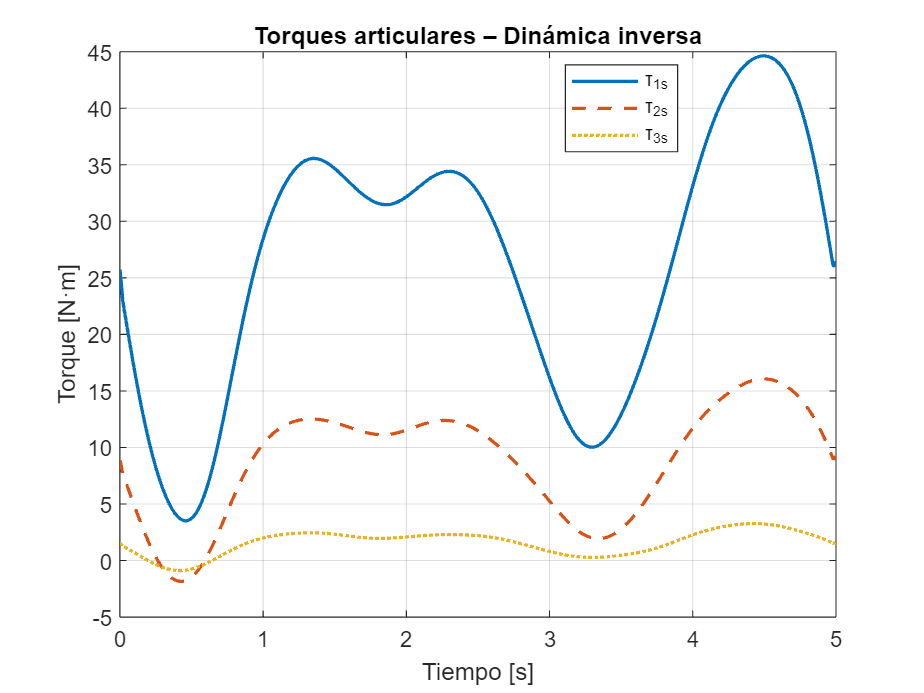

[m1_s, m2_s, m3_s, Ixx1_s, Iyy1_s, Izz1_s, Ixx2_s, Iyy2_s, Izz2_s, Ixx3_s, Iyy3_s, Izz3_s, x1C1_s, x2C2_s, x3C3_s, g_s] = deal(1.0, 0.8, 0.6, 0.01, 0.01, 0.01, 0.008, 0.008, 0.008, 0.005, 0.005, 0.005, 0.5, 0.4, 0.3, 9.81);

M_theta_num    = subs(M_theta,    {m_1,m_2,m_3, I_xx1,I_yy1,I_zz1, I_xx2,I_yy2,I_zz2, I_xx3,I_yy3,I_zz3, x_1_C1,x_2_C2,x_3_C3, g},  ...
                            {m1_s,    m2_s,    m3_s,    Ixx1_s, Iyy1_s, Izz1_s, Ixx2_s, Iyy2_s, Izz2_s, Ixx3_s, Iyy3_s, Izz3_s, x1C1_s, x2C2_s, x3C3_s, g_s});
V_theta_num    = subs(V_theta,    {m_1,m_2,m_3, I_xx1,I_yy1,I_zz1, I_xx2,I_yy2,I_zz2, I_xx3,I_yy3,I_zz3, x_1_C1,x_2_C2,x_3_C3, g},  ...
                            {m1_s,    m2_s,    m3_s,    Ixx1_s, Iyy1_s, Izz1_s, Ixx2_s, Iyy2_s, Izz2_s, Ixx3_s, Iyy3_s, Izz3_s, x1C1_s, x2C2_s, x3C3_s, g_s});
G_theta_num    = subs(G_theta,    {m_1,m_2,m_3,             x_1_C1,x_2_C2,x_3_C3, g},  ...
                            {m1_s,    m2_s,    m3_s,             x1C1_s, x2C2_s, x3C3_s, g_s});

Mfunc = matlabFunction(M_theta_num, 'Vars', {theta_O_1, theta_1_2, theta_2_3, L_1, L_2, L_3});
Vfunc = matlabFunction(V_theta_num, 'Vars', {theta_O_1, theta_1_2, theta_2_3, theta_dot_O_1, theta_dot_1_2, theta_dot_2_3, L_1, L_2, L_3});
Gfunc = matlabFunction(G_theta_num, 'Vars', {theta_O_1, theta_1_2, theta_2_3, L_1, L_2, L_3});

L1_s = 1.0;  L2_s = 0.8;  L3_s = 0.6;
T    = linspace(0,5,500);
q1_s = 0.5*sin(2*pi*0.4*T);
q2_s = 0.3*sin(2*pi*0.6*T + pi/6);
q3_s = 0.2*sin(2*pi*0.8*T - pi/8);

q1d_s  = gradient(q1_s, T);
q2d_s  = gradient(q2_s, T);
q3d_s  = gradient(q3_s, T);

q1dd_s = gradient(q1d_s, T);
q2dd_s = gradient(q2d_s, T);
q3dd_s = gradient(q3d_s, T);

Q_s   = [q1_s;  q2_s;  q3_s];
Qd_s  = [q1d_s; q2d_s; q3d_s];
Qdd_s = [q1dd_s;q2dd_s;q3dd_s];

TAU_s = inv_dynamics_scara(Mfunc, Vfunc, Gfunc, L1_s, L2_s, L3_s, Q_s, Qd_s, Qdd_s);

Qdd_direct_s = direct_dynamics_scara(Mfunc, Vfunc, Gfunc, L1_s, L2_s, L3_s, TAU_s, Q_s, Qd_s);

figure;
plot(T, TAU_s(1,:),'-', T, TAU_s(2,:), '--', T, TAU_s(3,:), ':','LineWidth',1.5);
legend('τ_1_s','τ_2_s','τ_3_s','Location','Best');
xlabel('Tiempo [s]'); ylabel('Torque [N·m]');
title('Torques articulares – Dinámica inversa');
grid on;

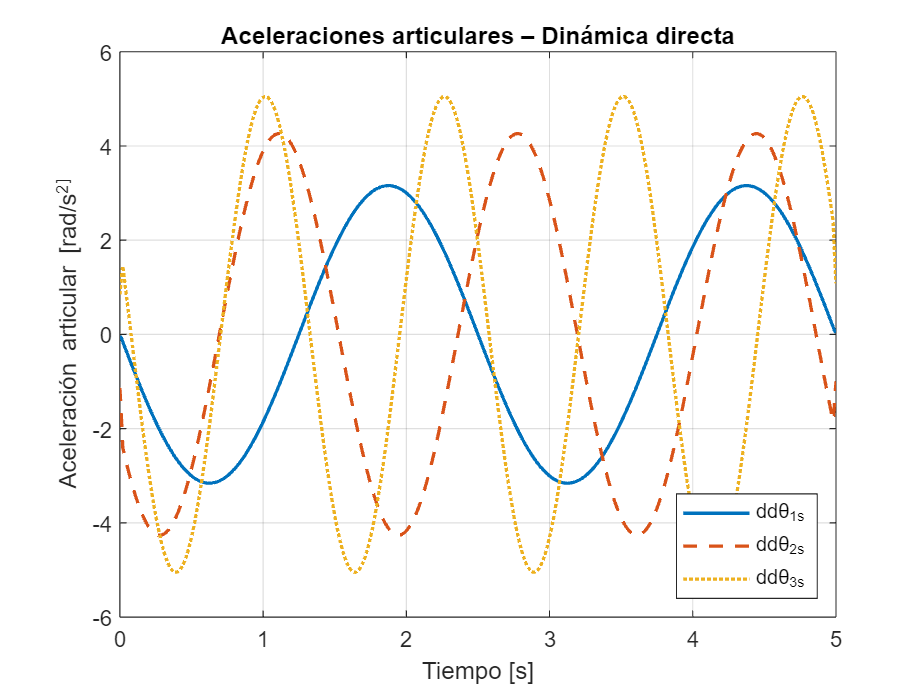


figure;
plot(T, Qdd_direct_s(1,:),'-', T, Qdd_direct_s(2,:), '--', T, Qdd_direct_s(3,:), ':','LineWidth',1.5);
legend('ddθ_1_s','ddθ_2_s','ddθ_3_s','Location','Best');
xlabel('Tiempo [s]'); ylabel('Aceleración articular [rad/s^2]');
title('Aceleraciones articulares – Dinámica directa');
grid on;

### Conclusiones

El objetivo principal de este examen consistía en, modelar una aproximación al comportamiento de un robot Scara RRR, incluyendo la cinemática y la dinámica, tanto directa como inversa, así como una simulación hipotética de su funcionamiento. 

La hipótesis inicial planteaba que serían suficientes los conceptos revisados en clase (modelos matemáticos directos e inversos para postura, velocidad y aceleración, así como la dinámica mediante el método de Euler-Lagrange) serían suficientes para cumplir con esta tarea. Tras el desarrollo se obtuvo un modelo de ecuaciones y simulaciones que se asemeja con lo que podríamos esperar en la realidad, por lo que se cumplió con el objetivo principal del examen haciendo uso de las herramientas aprendidas en clase.

Algunas posibles mejoras al modelo incluyen:

- Incluir fricción y efectos no lineales en las articulaciones

- Incluir en el modelo parámetros físicos y geométricos de un robot real y corroborar experimentalmente

- Generar un entorno se simulación en ROS que se valga de lo generado en este examen para una simulación más completa del robot

### Referencias

[1] J. J. Craig, *Introduction to Robotics: Mechanics and Control*, 3rd ed. Upper Saddle River, NJ, USA: Pearson Prentice Hall, 2005.

[2] B. Siciliano, L. Sciavicco, L. Villani, y G. Oriolo, *Robotics: Modelling, Planning and Control*. London, U.K.: Springer, 2010.

[3] M. W. Spong, S. Hutchinson, y M. Vidyasagar, *Robot Modeling and Control*. Hoboken, NJ, USA: John Wiley & Sons, 2005.

[4] R. Siegwart, I. R. Nourbakhsh, y D. Scaramuzza, *Introduction to Autonomous Mobile Robots*, 2nd ed. Cambridge, MA, USA: MIT Press, 2011.

[5] Yaskawa Motoman Robotics, “SCARA Robots,” YouTube, 2022. [En línea]. Disponible en: [https://www.youtube.com/watch?v=geYyK-zWsmI](https://www.youtube.com/watch?v=geYyK-zWsmI). [Accedido: 20-Abr-2025].

[6] ROS Robotics Learning, “Jacobian – Robotics and ROS,” 2023. [En línea]. Disponible en: [https://www.rosroboticslearning.com/jacobian](https://www.rosroboticslearning.com/jacobian). [Accedido: 22-Abr-2025].

[7] Northwestern Robotics, “S18 - Robot Dynamics: Euler Lagrange Formulation I,” YouTube, 2020. [En línea]. Disponible en: [https://www.youtube.com/watch?v=khT_-VD_8hg](https://www.youtube.com/watch?v=khT_-VD_8hg). [Accedido: 22-Abr-2025].

[8] Automatic Addison, “How To Perform a Pick and Place Task With a DIY SCARA Robot,” 2020. [En línea]. Disponible en: [https://automaticaddison.com/how-to-perform-a-pick-and-place-task-with-a-diy-scara-robot/](https://automaticaddison.com/how-to-perform-a-pick-and-place-task-with-a-diy-scara-robot/). [Accedido: 23-Abr-2025].

[9] A. S. Jacob y B. Dasgupta, “Dimensional synthesis of spatial manipulators for velocity and force transmission for operation around a specified task point,” *arXiv preprint arXiv:2210.04446*, 2022. [En línea]. Disponible en: [https://arxiv.org/abs/2210.04446](https://arxiv.org/abs/2210.04446). [Accedido: 25-Abr-2025].

[10] Wikipedia, “Robot kinematics,” 2025. [En línea]. Disponible en: [https://en.wikipedia.org/wiki/Robot_kinematics](https://en.wikipedia.org/wiki/Robot_kinematics). [Accedido: 20-Abr-2025]. 

[11] E. Peña Medina, "Modelado de la cinemática de un eslabón," YouTube, 23 mayo 2021. [En línea]. Disponible en: [https://www.youtube.com/watch?v=HDGwJO3kvbo](https://www.youtube.com/watch?v=HDGwJO3kvbo). [Accedido: 19-abr-2025].

[12] E. Peña Medina, "Modelado cinemático de un robot RRR en el plano," YouTube, 23 mayo 2021. [En línea]. Disponible en: [https://www.youtube.com/watch?v=Ffh_YCztMgM](https://www.youtube.com/watch?v=Ffh_YCztMgM). [Accedido: 19-abr-2025].

[13] E. Peña Medina, "Modelado dinámico de un robot serial RRR en el plano," YouTube, 23 mayo 2021. [En línea]. Disponible en: [https://www.youtube.com/watch?v=T_umUStA-mo](https://www.youtube.com/watch?v=T_umUStA-mo). [Accedido: 19-abr-2025].

[14] E. Peña Medina, *Clase de Robótica*, Facultad de Ingeniería, Universidad Nacional Autónoma de México (UNAM), México, 2025.

### Definición de funciones

function [P, xi_O_P] = direct_kin_scara(x_O_1, y_O_1, L1, L2, L3, theta_O_1, theta_1_2, theta_2_3)
%DIRECT_KIN_SCARA Cinemática directa del robot SCARA planar R–R–R
%   [P, xi_O_P] = direct_kin_scara(x0, y0, L1, L2, L3, th1, th2, th3)
%   devuelve:
%     P       = 2×4 matriz de posiciones [p0 p1 p2 p3] en (x,y)
%     xi_O_P  = [x_P; y_P; phi] vector de postura del efector

  p0 = [x_O_1; y_O_1];

  phi1 = theta_O_1;
  phi2 = phi1 + theta_1_2;
  phi3 = phi2 + theta_2_3;

  p1 = p0 + L1*[cos(phi1); sin(phi1)];
  p2 = p1 + L2*[cos(phi2); sin(phi2)];
  p3 = p2 + L3*[cos(phi3); sin(phi3)];

  P = [p0, p1, p2, p3];
  xi_O_P = [p3(1); p3(2); phi3];
end

function theta = inv_kin_scara(xP, yP, phi, L1, L2, L3)
%INV_KIN_SCARA Cinemática inversa para robot SCARA planar R–R–R
%   theta = inv_kin_scara(xP,yP,phi,L1,L2,L3) devuelve
%   theta = [θ1; θ2; θ3] 

  xw = xP - L3*cos(phi);
  yw = yP - L3*sin(phi);

  c2 = (xw^2 + yw^2 - L1^2 - L2^2) / (2*L1*L2);
  c2 = max(min(c2,1),-1);     
  th2 = acos(c2);

  th1 = atan2(yw, xw) ...
        - atan2(L2*sin(th2), L1 + L2*cos(th2));

  th3 = phi - th1 - th2;

  theta = [th1; th2; th3];
end

function xidot = direct_vel_scara(Jtheta_handle, L1_s, L2_s, L3_s, th1_s, th2_s, th3_s, dth1_s, dth2_s, dth3_s)
%DIRECT_VEL_SCARA Cinemática directa de velocidades para robot SCARA planar R–R–R
%   xidot = direct_vel_scara(Jtheta_handle, L1, L2, L3, th1, th2, th3, dth1, dth2, dth3)
%   devuelve el vector de velocidades cartesianas [vx; vy; omega].
%
%   Entradas:
%     Jtheta_handle : handle al Jacobiano, generado por matlabFunction del J_theta simbólico
%     L1_s, L2_s, L3_s : longitudes de eslabones [m]
%     th1_s, th2_s, th3_s : ángulos articulares [rad]
%     dth1_s, dth2_s, dth3_s : velocidades articulares [rad/s]

  J_eval = Jtheta_handle(th1_s, th2_s, th3_s, L1_s, L2_s, L3_s);

  dq_vec = [dth1_s; dth2_s; dth3_s];

  xidot = J_eval * dq_vec;
end

function dq = inv_vel_scara(Jtheta_handle, L1_s, L2_s, L3_s, vx_s, vy_s, omega_s, th1_s, th2_s, th3_s)
%INV_VEL_SCARA Cinemática inversa de velocidades para robot SCARA planar R–R–R
%   dq = inv_vel_scara(Jtheta_handle,L1,L2,L3,vx,vy,omega,th1,th2,th3)
%   devuelve el vector de velocidades articulares [dth1; dth2; dth3]
%
% Entradas:
%   Jtheta_handle : handle al Jacobiano simbólico (matlabFunction)
%   L1_s, L2_s, L3_s : longitudes de eslabones [m]
%   vx_s, vy_s, omega_s : velocidades cartesianas del efector
%   th1_s, th2_s, th3_s : ángulos articulares actuales [rad]

  J_eval = Jtheta_handle(th1_s, th2_s, th3_s, L1_s, L2_s, L3_s);

  xidot = [vx_s; vy_s; omega_s];

  dq = J_eval \ xidot;
end

function xacc = direct_acc_scara(Jtheta_handle, Jdot_handle, ...
                                 L1_s, L2_s, L3_s, ...
                                 th1_s, th2_s, th3_s, ...
                                 dth1_s, dth2_s, dth3_s, ...
                                 ddth1_s, ddth2_s, ddth3_s)
%DIRECT_ACC_SCARA Cinemática directa de aceleraciones para robot SCARA planar R–R–R
%   xacc = direct_acc_scara(Jtheta_handle, Jdot_handle, L1, L2, L3, th1, th2, th3, dth1, dth2, dth3, ddth1, ddth2, ddth3)
%   devuelve el vector de aceleraciones cartesianas [ax; ay; alpha] donde:
%     Jtheta_handle: handle al Jacobiano simbólico (matlabFunction)
%     Jdot_handle:   handle a la derivada temporal del Jacobiano (matlabFunction)
%     L1_s,L2_s,L3_s: longitudes [m]
%     th*_s:         ángulos [rad]
%     dth*_s:        velocidades articulares [rad/s]
%     ddth*_s:       aceleraciones articulares [rad/s^2]

  J_eval    = Jtheta_handle(th1_s, th2_s, th3_s, L1_s, L2_s, L3_s);
  Jdot_eval = Jdot_handle(th1_s, th2_s, th3_s, dth1_s, dth2_s, dth3_s, L1_s, L2_s, L3_s);

  dq    = [dth1_s; dth2_s; dth3_s];
  ddq   = [ddth1_s; ddth2_s; ddth3_s];

  xacc = J_eval*ddq + Jdot_eval*dq;
end

function ddth = inv_acc_scara(Jtheta_handle, Jdot_handle, ...
                                 L1_s, L2_s, L3_s, ...
                                 th1_s, th2_s, th3_s, ...
                                 dth1_s, dth2_s, dth3_s, ...
                                 ddx_s, ddy_s, ddphi_s)
%INV_ACC_SCARA Cinemática inversa de aceleraciones para robot SCARA planar R–R–R
%   ddth = inv_acc_scara(Jtheta_handle,Jdot_handle,...
%                        L1,L2,L3, th1,th2,th3, dth1,dth2,dth3, ddx,ddy,ddphi)
%   devuelve el vector de aceleraciones articulares [ddth1; ddth2; ddth3]
%
% Entradas:
%   Jtheta_handle : handle al Jacobiano simbólico (matlabFunction)
%   Jdot_handle   : handle a la derivada simbólica del Jacobiano
%   L1_s,L2_s,L3_s: longitudes de eslabones [m]
%   th1_s,th2_s,th3_s: ángulos de junta [rad]
%   dth1_s,dth2_s,dth3_s: velocidades articulares [rad/s]
%   ddx_s,ddy_s,ddphi_s : aceleraciones cartesiana deseadas [m/s^2, rad/s^2]

  J_eval    = Jtheta_handle(th1_s, th2_s, th3_s, L1_s, L2_s, L3_s);
  Jdot_eval = Jdot_handle(th1_s, th2_s, th3_s, dth1_s, dth2_s, dth3_s, L1_s, L2_s, L3_s);

  ddxi = [ddx_s; ddy_s; ddphi_s] - Jdot_eval * [dth1_s; dth2_s; dth3_s];

  ddth = J_eval \ ddxi;
end

function Qdd = direct_dynamics_scara(Mfunc, Vfunc, Gfunc, L1, L2, L3, tau, Q, Qd)
%DIRECT_DYNAMICS_SCARA Dinámica directa para robot SCARA planar R–R–R
%   Qdd = direct_dynamics_scara(Mfunc,Vfunc,Gfunc,L1,L2,L3,tau,Q,Qd)
%   calcula aceleraciones articulares Qdd (3×N) dada la entrada de pares tau.
%
% Entradas:
%   tau : 3×N matriz de pares articulares [τ1;τ2;τ3]
%   Q   : 3×N matriz de ángulos articulares
%   Qd  : 3×N matriz de velocidades articulares

  N = size(Q,2);
  Qdd = zeros(3,N);
  for k = 1:N
    q   = Q(:,k);
    qd  = Qd(:,k);
    t   = tau(:,k);
    M   = Mfunc(q(1),q(2),q(3),L1,L2,L3);
    V   = Vfunc(q(1),q(2),q(3),qd(1),qd(2),qd(3),L1,L2,L3);
    G   = Gfunc(q(1),q(2),q(3),L1,L2,L3);
    Qdd(:,k) = M \ (t - V - G);
  end
end

function TAU = inv_dynamics_scara(Mfunc, Vfunc, Gfunc, L1_s, L2_s, L3_s, Q_s, Qd_s, Qdd_s)
%INV_DYNAMICS_SCARA Dinámica inversa para robot SCARA planar R–R–R
%   TAU = inv_dynamics_scara(Mfunc,Vfunc,Gfunc,L1_s,L2_s,L3_s,Q_s,Qd_s,Qdd_s)
%   devuelve TAU (3×N) con los pares articulares para cada instante.
%
% Entradas:
%   Mfunc : handle a la matriz de inercia M(q)
%   Vfunc : handle al vector de Coriolis/centrífuga V(q,qdot)
%   Gfunc : handle al vector de gravedad G(q)
%   L1_s, L2_s, L3_s : longitudes de eslabones [m]
%   Q_s   : 3×N matriz de ángulos articulares [th1_s;th2_s;th3_s]
%   Qd_s  : 3×N matriz de velocidades articulares [th1d_s;th2d_s;th3d_s]
%   Qdd_s : 3×N matriz de aceleraciones articulares [th1dd_s;th2dd_s;th3dd_s]

  N = size(Q_s,2);
  TAU = zeros(3,N);
  for k = 1:N
    q   = Q_s(:,k);
    qd  = Qd_s(:,k);
    qdd = Qdd_s(:,k);
    TAU(:,k) = Mfunc(q(1),q(2),q(3),L1_s,L2_s,L3_s)*qdd + ...
               Vfunc(q(1),q(2),q(3),qd(1),qd(2),qd(3),L1_s,L2_s,L3_s) + ...
               Gfunc(q(1),q(2),q(3),L1_s,L2_s,L3_s);
  end
end